# Integración por partes 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

La integración por partes es un método de integración extremadamente poderoso que solo se enfocará por completo una vez que lo apliques a la resolución de ecuaciones diferenciales. Por el momento, sin embargo, te permitirá resolver algunas integrales con las que la sustitución no ayuda. 

 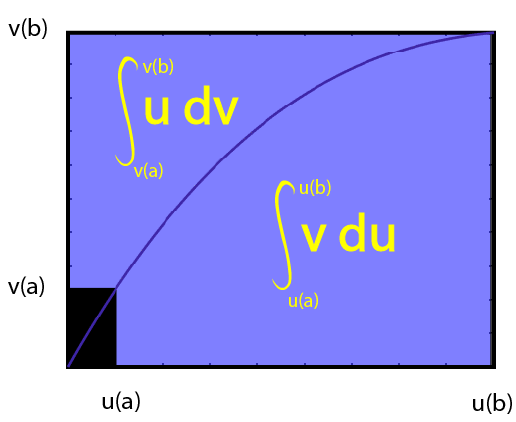

La integración por partes le permite subdividir su integrando en componentes integrados y diferenciados y recombinar esas piezas de maneras que puedan ser más fáciles de calcular. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB.

##  Integración por partes geométricamente 


$$u(b)v(b)-u(a)v(a) = \int_{v(a)}^{v(b)}u(v)\;dv + \int_{u(a)}^{u(b)}v(u)\; du \;\;\;\;\;\;\; (3)$$


 

El lado izquierdo de la ecuación $(3)$ es la diferencia de los dos rectángulos mientras que el lado derecho de la ecuación $(3)$ subdivide la misma región en una suma de dos partes divididas por la curva $(u,v)$. En la práctica, expresar $u$ como una función de $v$ o viceversa puede ser complejo algebraicamente, pero es sencillo geométricamente usando la parametrización en términos de $t$: 

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = -5;
b = 5;
 
tl = tiledlayout(1,2);
if a < b
    tVals = a:.01:b;
else
    warning("Deberías elegir a < b.")
    tVals = b:.01:a;
end
uVals = u(tVals);
vVals = v(tVals);
nexttile
plot(uVals,vVals)
title("Trazado de $v$ como funci\'on de $u$","Interpreter","latex")
xlabel("$u(t)$","Interpreter","latex")
ylabel("$v(t)$","Interpreter","latex")
axis square
nexttile
plot(vVals,uVals)
title("Trazado de $u$ como funci\'on de $v$","Interpreter","latex")
xlabel("$v(t)$","Interpreter","latex")
ylabel("$u(t)$","Interpreter","latex")
axis square 

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = 1;
b = 3;
 
if a>b
    disp("Este código requiere que b>a. Tus puntos finales han sido invertidos.")
    ar = b;
    br = a;
else
    ar = a;
    br = b;
end
tVals = ar:.01:br;
numSteps = length(tVals);
uVals = u(tVals);
vVals = v(tVals);
z = zeros(size(tVals));
p = plot(uVals,vVals);
ax = p.Parent;
title("Integración por Partes Geométrica")
hold on
xlabel("u(t)")
ylabel("v(t)")
v0 = double(v(0));
u0 = double(u(0));
[hx,hy,dUPosRegions,dUNegRegions,dULines] = PlotRegions(vVals,uVals,v0,["r" "b"],"h");
[vx,vy,dVPosRegions,dVNegRegions,dVLines] = PlotRegions(uVals,vVals,u0,["r" "b"],"v");
rectGrp = DrawRectangles(uVals,vVals,u0,v0);
surface([uVals;uVals],[vVals;vVals],[z;z],[tVals;tVals],...
    "FaceColor","none","EdgeColor","interp","LineWidth",2)
hold off
SetXTicks(ax,double([u(ar) u(br)]),["u(a)" "u(b)"])
SetYTicks(ax,double([v(ar) v(br)]),["v(a)" "v(b)"]) 

showPosdUReg = true; showNegdUReg = true;
showPosdVReg = false; showNegdVReg = false;
showRectSubs = true; hideVertStripes = false;    hideHorizStripes = true;
if showPosdUReg
    dUPosRegions.Visible = "on";
else
    dUPosRegions.Visible = "off"; %#ok<*UNRCH> 
end
if showNegdUReg
    dUNegRegions.Visible = "on";
else
    dUNegRegions.Visible = "off";
end
if showPosdVReg
    dVPosRegions.Visible = "on";
else
    dVPosRegions.Visible = "off";
end
if showNegdVReg
    dVNegRegions.Visible = "on";
else
    dVNegRegions.Visible = "off";
end
if hideVertStripes
    dULines.Visible = "off";
else
    dULines.Visible = "on";
end
if hideHorizStripes 
    dVLines.Visible = "off";
else
    dVLines.Visible = "on";
end
if showRectSubs
    rectGrp.Visible = "on";
else
    rectGrp.Visible = "off";
end

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña** View **y cambie a **Output inline**. Como alternativa, seleccione **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

** Crear visualizaciones de integración por partes **

Trazar regiones 

function [x,y,posRegGroup,negRegGroup,LinesGroup] = PlotRegions(fVals,dVals,f0,cols,hvflag)
posRegGroup = hggroup;
negRegGroup = hggroup;
LinesGroup = hggroup;
regGrpChoice = [negRegGroup posRegGroup];
dU = double(dVals(2:end)-dVals(1:end-1));
posDU = dU >= 0;
posF = double(fVals(1:end-1))>=0;
fSignChange = posF(2:end)-posF(1:end-1);
fSignChangeIdx = find(fSignChange~=0);
dUSignChange = (posDU(2:end)-posDU(1:end-1));
dUSignChangeIdx =  find(dUSignChange~=0);
dUSignChangeIdx = [1 (dUSignChangeIdx + 1) length(dVals)];
scIdx = unique(sort([dUSignChangeIdx fSignChangeIdx]),"sorted");
scVal = (posDU(scIdx(1:end-1))==posF(scIdx(1:end-1)))+1;
alphaVal = 1/(length(scIdx)-1);
for k = 1:length(scIdx)-1
    xU = dVals(scIdx(k):scIdx(k+1)-1);
    x = double([xU flip(xU)]);
    yV = fVals(scIdx(k):scIdx(k+1)-1);
    y = double([f0*ones(size(yV)) flip(yV)]);
    if hvflag == "h"
        patch(x,y,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"v",10,LinesGroup);
    else
        patch(y,x,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"h",10,LinesGroup);
    end
end
end 

Agregar franjas 

function lineGroup = AddStripes(x,y,hvflag,step,lineGroup)
    % x and y are the same length, so this is just determining the bin
    % index value based on the relative sizes of the number of rectangles
    % length(x)/2 and step
    idx = DefStripes(length(x)/2,step);
    if length(idx)>1
        if hvflag == "v"       
            try
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
                lineGroup.Children(k).YData = [y(idx(k)) y(end-idx(k))];
            end
            drawnow
        else
            try
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [y(idx(k)) y(end-idx(k))];
                lineGroup.Children(k).YData = [x(idx(k)) x(idx(k))];
            end
            drawnow
        end
    end
end


function idx = DefStripes(numRect,step)
    numBins = floor(numRect/step);
    if numRect > step
         rem = mod(numRect,step);
         if (rem == 0) && (numBins > 0)
             idx = 0:step:numRect;
             idx(1) = 1;
         elseif numBins >= rem
             intro = 1:(step+1):floor(rem/2)*(step+1);
             middle = floor(rem/2)*(step+1):step:(numRect-(step+1)*ceil(rem/2));
             last = (numRect-(step+1)*ceil(rem/2)):step+1:numRect;
             idx = [intro middle(2:end-1) last];
         else
            idx = 1:(ceil(rem/numBins)+step):numRect;
            if idx(end) ~= numRect
                idx = [idx numRect];
            end
         end
    else
        idx = unique([1 numRect]);
    end
end 

Dibujar rectángulos 

function rectObj = DrawRectangles(uVals,vVals,u0,v0)
rectObj = hggroup;
ua = double(uVals(1));
ub = double(uVals(end));
va = double(vVals(1));
vb = double(vVals(end));
ax = gca;
col = colormap;
fgcol = round(ax.Parent.Color); % color de la figura principal fijado en blanco/negro
bkcol = round(ax.GridColor); % color de acento fijado en blanco y negro
if (ua>u0)~=(va>v0)
    fCol = fgcol;
else
    fCol = bkcol;
end
if (ub>u0)~=(vb>v0)
    lCol = col(3,:); % Tercer color de acento, generalmente amarillo.
else
    lCol = bkcol;
end
rectangle("Position",[min(u0,ua) min(v0,va) abs(ua-u0) abs(va-v0)],...
    "FaceColor",fCol,"EdgeColor",bkcol,"LineWidth",2,"Parent",rectObj);
rectangle("Position",[min(u0,ub) min(v0,vb) abs(ub-u0) abs(vb-v0)],...
    "FaceColor","none","LineWidth",3,"Parent",rectObj,"EdgeColor",lCol);
end


** Agregar etiquetas de puntos finales a los ejes **

function SetXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end

function SetYTicks(ax,newVals,newNames)
TickSpacing = .5*(ax.YTick(2)-ax.YTick(1));
remYVals = ax.YTick((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
starYN = string(cell2mat(pad(ax.YTickLabel)));
remYN = starYN((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[yV,idx] = sort([newVals remYVals]);
allNames = [newLabel remYN'];
yN = allNames(idx);
yticks(ax,yV);
yticklabels(ax,yN);
end